# `TRC_V3_UpdateInterpret.mlx`

`Davis Reina-Guerra`

Saved Monster6_01 data inC:\Users\davis\OneDrive\Desktop\MonsterV3\Data\Monster6\01_Training1\Monster6_01
Saved Monster6_02 data inC:\Users\davis\OneDrive\Desktop\MonsterV3\Data\Monster6\01_Training1\Monster6_02
Saved Monster6_03 data inC:\Users\davis\OneDrive\Desktop\MonsterV3\Data\Monster6\01_Training1\Monster6_03
Saved Monster6_04 data inC:\Users\davis\OneDrive\Desktop\MonsterV3\Data\Monster6\01_Training1\Monster6_04
Saved Monster6_05 data inC:\Users\davis\OneDrive\Desktop\MonsterV3\Data\Monster6\01_Training1\Monster6_05
Saved Monster6_07 data inC:\Users\davis\OneDrive\Desktop\MonsterV3\Data\Monster6\01_Training1\Monster6_07
Saved Monster6_09 data inC:\Users\davis\OneDrive\Desktop\MonsterV3\Data\Monster6\01_Training1\Monster6_09
Saved Monster6_10 data inC:\Users\davis\OneDrive\Desktop\MonsterV3\Data\Monster6\01_Training1\Monster6_10
Saved Monster6_11 data inC:\Users\davis\OneDrive\Desktop\MonsterV3\Data\Monster6\01_Training1\Monster6_11
Saved Monster6_01 data inC:\Users\davis\OneDri

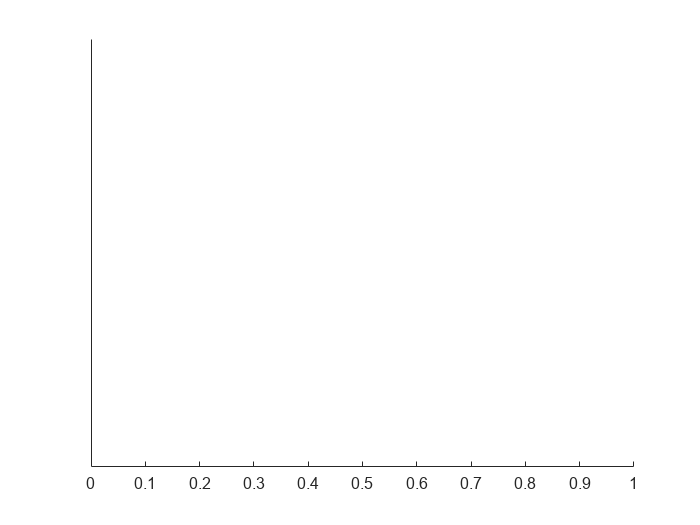

Saved Monster6_11 data inC:\Users\davis\OneDrive\Desktop\MonsterV3\Data\Monster6\10_NoThreat4\Monster6_11


% Add all folders and subfolders to path
thisFile = mfilename('fullpath');
[thisDir, ~, ~] = fileparts(thisFile);
addpath(genpath(thisDir));

% Get all the data folders for a given experiment
experiment_folder = uigetdir([], 'Select the Experiment Folder');
subject_dirs = dir(fullfile(experiment_folder, '*', '*')); % Animal Code Folder
subject_dirs = subject_dirs([subject_dirs.isdir]); % Keep only directories (maybe unnecessary but good form to leave in)
subject_dirs = subject_dirs(~ismember({subject_dirs.name}, {'.', '..'}));
subject_paths = fullfile({subject_dirs.folder}, {subject_dirs.name});

% For testing 
home = pwd;

for y = 1:length(subject_paths)
    clearvars -except home subject_paths y
    cd(home)
    cd(subject_paths{y})
    numAddressesIn = 16;
    sample_rate = 2000;
    load("configset.mat")
    %delete("Raw_1001.mat"); 
    D=dir('Raw_*.mat');
    filename={D.name};
    output=zeros(1,(length(filename)*(sample_rate*numAddressesIn)));
    for i=1:length(D)
        load(filename{i});
        output(((i-1)*(sample_rate*numAddressesIn)+1):(i*(sample_rate*numAddressesIn)))=temp;
    end
    cd(home);
    totalLen = length(output);
    % Create variables which contain the relevant values
    raw_PD_green    =output(find(mod(1:totalLen,numAddressesIn)==1));     % photodetector green
    raw_PD_red      =output(find(mod(1:totalLen,numAddressesIn)==2));     % photodetector red
    Mod_green       =output(find(mod(1:totalLen,numAddressesIn)==3));     % DAC0 167Hz Mod Copy (green)
    Mod_red         =output(find(mod(1:totalLen,numAddressesIn)==4));     % DAC1 223Hz Mod Copy (red)
    d2_reward_report=output(find(mod(1:totalLen,numAddressesIn)==5));     % d2: Reward Report
    d3_null         =output(find(mod(1:totalLen,numAddressesIn)==6));     % d3: -
    d4_enterIR      =output(find(mod(1:totalLen,numAddressesIn)==7));     % d4: enterIR
    d5_trigIR       =output(find(mod(1:totalLen,numAddressesIn)==8));     % d5: trigIR
    d6_nestIR       =output(find(mod(1:totalLen,numAddressesIn)==9));     % d6: nestIR
    d7_null         =output(find(mod(1:totalLen,numAddressesIn)==10));    % d7: -
    d8_loom         =output(find(mod(1:totalLen,numAddressesIn)==11));    % d8: loom
    d9_crescendo    =output(find(mod(1:totalLen,numAddressesIn)==12));    % d9: crescendo
    d10_trial       =output(find(mod(1:totalLen,numAddressesIn)==13));    % d10: trial
    d11_running     =output(find(mod(1:totalLen,numAddressesIn)==14));    % d11: running
    d12_lick        =output(find(mod(1:totalLen,numAddressesIn)==15));    % d12: Lick
    d13_reward      =output(find(mod(1:totalLen,numAddressesIn)==16));    % d13: Reward
    
    try
        % Creates a params struct
        params.freqStep   = 5;          % Step size in Hz for freqency calculations
        params.freqRange1 = [125 200];  % Min and max frequency range for channel 1 (target 167 Hz) (ex 125-200)
        params.freqRange2 = [200 275];  % Min and max frequency range for channel 2 (target 223 Hz) (ex 200-275)
        params.winSize = 0.04;          % Target window size (in sec) for FFT frequency calc (80 samples)
        params.spectSample = 0.01;      % Step size for spectrogram (sec)
        params.inclFreqWin = 4;         % Number of frequency bins to average (on either side of peak freq)
        params.filtCut = 100;           % Cut off frequency for low pass filter of processed data
        params.filtCutOsc = 500;        % Cut-off frequency for low-pass filter of oscillation data.
        params.dsRate = 0.05;           % Time steps for down-sampling (seconds) (average of every 100 samples)
        
        % Calculate Spectrograms for Channel 1 and 2
        useFreqRange1 = params.freqRange1(1):params.freqStep:params.freqRange1(2);
        [filtTimes, filtSig1, rawSig1, spectFreqs1, spectAmpVals1] = sfoReadFibPhot(raw_PD_green, sample_rate, useFreqRange1, params);
        useFreqRange2 = params.freqRange2(1):params.freqStep:params.freqRange2(2);
        [filtTimes, filtSig2, rawSig2, spectFreqs2, spectAmpVals2] = sfoReadFibPhot(raw_PD_red, sample_rate, useFreqRange2, params);
        % Determine downsampled time points in output data set
        dsTimes = filtTimes(1):params.dsRate:filtTimes(end); 

        % Fit: Fit each channel to exponential decay for photobleaching correction
        pbFit1 = fit(filtTimes',filtSig1','exp2'); 
        pbFit2 = fit(filtTimes',filtSig2','exp2');
        
        % Correction: Divide filtered signal by exponential decay to correct for photobleaching
        pbVals1 = (filtSig1' ./ double(pbFit1(filtTimes)))';
        pbVals2 = (filtSig2' ./ double(pbFit2(filtTimes)))';
        
        % Downsample raw (uncorrected) data
        g_dsVals_raw = interp1(filtTimes,filtSig1',dsTimes,'spline');
        r_dsVals_raw = interp1(filtTimes,filtSig2',dsTimes,'spline');
        
        % Downsample photobleaching-corrected data
        g_dsVals = interp1(filtTimes,pbVals1,dsTimes,'spline');
        r_dsVals = interp1(filtTimes,pbVals2,dsTimes,'spline');

        % Calculate Photometry Values
        Fs=20; % Downsampled Frequency = 20Hz
        g_0 = running_percentile(g_dsVals, floor(Fs*10), 10);
        g_dff = g_dsVals'./g_0 - 1;
        g_dff = g_dff';
        r_0 = running_percentile(r_dsVals, floor(Fs*10), 10);
        r_dff = r_dsVals'./r_0 - 1;
        r_dff = r_dff';
        g_deriv = diff(g_dsVals');
        r_deriv = diff(r_dsVals');
        g_deriv = g_deriv';
        r_deriv = r_deriv';
        g_deriv = [zeros(1, max(0, 1)), g_deriv];
        r_deriv = [zeros(1, max(0, 1)), r_deriv];
        zscore_g_dsVals = zscore(g_dsVals);
        zscore_r_dsVals = zscore(r_dsVals);
        zscore_g_deriv = zscore(g_deriv);
        zscore_r_deriv = zscore(r_deriv);
    catch
        disp("no photometry to be found")
    end
    Data = table();
    
    trial_indices = [1 find(diff(d10_trial) == 1)];
    ds_trial_indices = [1 round(trial_indices(2:end)/100)];
    n_trials = length(trial_indices) - 1;
    
    % Data Vector Initialization
    sucessses = zeros(n_trials, 1);
    failure_to_lick = zeros(n_trials, 1);
    failure_to_trigger = zeros(n_trials, 1);
    trial_duration = zeros(n_trials, 1);
    latency_to_trigger = zeros(n_trials, 1);
    escape_after_trigger = zeros(n_trials, 1);
    trigger_to_lick = zeros(n_trials, 1);
    time_spent_licking = zeros(n_trials, 1);
    escape_after_last_lick = zeros(n_trials, 1);
    latency_to_lick = zeros(n_trials, 1);
    
    first_trigger_on_idx = zeros(n_trials, 1);
    last_trigger_off_idx = zeros(n_trials, 1);
    first_lick_idx = zeros(n_trials, 1);
    last_lick_idx = zeros(n_trials, 1);
    first_nest_on_idx = zeros(n_trials, 1);
    last_nest_on_idx = zeros(n_trials, 1);
    
    for i = 1:n_trials
      
        start_idx = trial_indices(i);
        end_idx = trial_indices(i+1);
        trial_length = end_idx-start_idx;
    
        % Nest IR
        nest = d6_nestIR(start_idx:end_idx);
        nest_on = find(diff(nest) == -1); % for IR sensors, diff() = -1 means onset
        nest_off = find(diff(nest) == 1); % for IR sensors, diff() = 1 means offset
        try
            first_nest_on_idx(i) = nest_on(1);
            last_nest_on_idx(i) = nest_on(end);
        catch
            first_nest_on_idx(i) = NaN;
            last_nest_on_idx(i) = NaN;
        end
    
        % Trigger IR
        trigger = d5_trigIR(start_idx:end_idx);
        triggers_on_idx = find(diff(trigger) == -1); % for IR sensors, diff() = -1 means onset
        triggers_off_idx = find(diff(trigger) == 1); % for IR sensors, diff() = 1 means offset
        if isempty(triggers_on_idx)
            failure_to_trigger(i) = 1;
        else
            first_trigger_on_idx(i) = triggers_on_idx(1);
            last_trigger_off_idx(i) = triggers_off_idx(end);
        end
    
        % Lick Sensor
        lick = d12_lick(start_idx:end_idx);
        lick_idx = find(diff(lick) == 1);
        if isempty(lick_idx)
            failure_to_lick(i) = 1;
        else
            first_lick_idx(i) = lick_idx(1);
            last_lick_idx(i) = lick_idx(end);
        end
    
        % If did not trigger and did not lick
        if failure_to_trigger(i) == 1 && failure_to_lick(i) == 1
            % Calculate Variables
            trial_duration(i) = trial_length/sample_rate;
            latency_to_trigger(i) = NaN;
            latency_to_lick(i) = NaN;
            escape_after_trigger(i) = NaN;
            trigger_to_lick(i) = NaN;
            time_spent_licking(i) = NaN;
            escape_after_last_lick(i) = NaN;
        end
    
        % If triggered but did not lick
        if failure_to_trigger(i) == 0 && failure_to_lick(i) == 1
            % Calculate Variables
            trial_duration(i) = trial_length/sample_rate;
            latency_to_trigger(i) = first_trigger_on_idx(i)/sample_rate;
            latency_to_lick(i) = NaN;
            escape_after_trigger(i) = (last_nest_on_idx(i)-first_trigger_on_idx(i))/sample_rate;
            trigger_to_lick(i) = NaN;
            time_spent_licking(i) = NaN;
            escape_after_last_lick(i) = NaN;
        end
    
        % If triggered and licked
        if failure_to_trigger(i) == 0 && failure_to_lick(i) == 0
            % Calculate Variables
            trial_duration(i) = trial_length/sample_rate;
            latency_to_trigger(i) = first_trigger_on_idx(i)/sample_rate;
            latency_to_lick(i) = first_lick_idx(i)/sample_rate;
            escape_after_trigger(i) = (last_nest_on_idx(i)-first_trigger_on_idx(i))/sample_rate;
            if first_lick_idx(i) < first_trigger_on_idx(i)
                trigger_to_lick(i) = 0;
                latency_to_trigger(i) = latency_to_lick(i);
            else
                trigger_to_lick(i) = (first_lick_idx(i)-first_trigger_on_idx(i))/sample_rate;
            end
            time_spent_licking(i) = (last_lick_idx(i)-first_lick_idx(i))/sample_rate;
            escape_after_last_lick(i) = (last_nest_on_idx(i)-last_lick_idx(i))/sample_rate;
        end
    
        % If licked but did not trigger
        % So fast they licked before trigger read
        if failure_to_trigger(i) == 1 && failure_to_lick(i) == 0
            % fix failure to trigger
            failure_to_trigger(i) = 0;
            % Calculate Variables
            trial_duration(i) = trial_length/sample_rate;
            latency_to_trigger(i) = first_lick_idx(i)/sample_rate;
            latency_to_lick(i) = first_lick_idx(i)/sample_rate;
            escape_after_trigger(i) = (last_nest_on_idx(i)-first_lick_idx(i))/sample_rate;
            trigger_to_lick(i) = 0;
            time_spent_licking(i) = (last_lick_idx(i)-first_lick_idx(i))/sample_rate;
            escape_after_last_lick(i) = (last_nest_on_idx(i)-last_lick_idx(i))/sample_rate;
        end
    end
    Data.("Successes") = double(~failure_to_lick);
    Data.("Failure_To_Lick") = failure_to_lick;
    Data.("Failure_To_Trigger") = failure_to_trigger;
    Data.("Trial_Duration") = trial_duration;
    Data.("Latency_To_Trigger") = latency_to_trigger;
    Data.("Latency_To_Lick") = latency_to_lick;
    Data.("Escape_Duration_After_Trigger") = escape_after_trigger;
    Data.("Trigger_To_Lick") = trigger_to_lick;
    Data.("Time_Spent_Licking") = time_spent_licking;
    Data.("Escape_Duration_After_Last_Lick") = escape_after_last_lick;

    try
        timetemp=linspace(0,length(raw_PD_green)/sample_rate,length(raw_PD_green));
        sec_before = 1;
        sec_after = 4;
        % Lick Alignments
        ds_lick = interp1(timetemp,d12_lick,dsTimes);
        deriv_lick = diff(ds_lick);
        lick_onset_idx = find(deriv_lick > 0);
        lick_offset_idx = find(deriv_lick < 0);
        lick_onset_idx = lick_onset_idx(lick_onset_idx > Fs*sec_before);
        lick_offset_idx = lick_offset_idx(lick_offset_idx > Fs*sec_before);
        % Lick Alignments
        ds_reward = interp1(timetemp,d2_reward_report,dsTimes);
        deriv_reward = diff(ds_reward);
        reward_onset_idx = find(deriv_reward > 0);
        reward_offset_idx = find(deriv_reward < 0);
        reward_onset_idx = reward_onset_idx(reward_onset_idx > Fs*sec_before);
        reward_offset_idx = reward_offset_idx(reward_offset_idx > Fs*sec_before);
        try
            reward_onset_idx = reward_onset_idx(reward_onset_idx < (reward_onset_idx(end) - Fs*sec_after));
            reward_offset_idx = reward_offset_idx(reward_offset_idx < (reward_offset_idx(end) - Fs*sec_after));
        catch
        end
        %Threat Alignments
        ds_threat = interp1(timetemp,d8_loom,dsTimes);
        deriv_threat = diff(ds_threat);
        threat_onset_idx = find(deriv_threat > 0);
        threat_offset_idx = find(deriv_threat < 0);
        threat_onset_idx = threat_onset_idx(threat_onset_idx > Fs*sec_before);
        threat_offset_idx = threat_offset_idx(threat_offset_idx > Fs*sec_before);
        try
            threat_onset_idx = threat_onset_idx(threat_onset_idx < (threat_onset_idx(end) - Fs*sec_after));
            threat_offset_idx = threat_offset_idx(threat_offset_idx < (threat_offset_idx(end) - Fs*sec_after));
        catch
        end
        
        % Create Photometry Struct
        photometry = struct();
        
        % Unaligned data
        photometry.g_dsVals_raw = g_dsVals_raw;
        photometry.r_dsVals_raw = r_dsVals_raw;
        photometry.g_dsVals = g_dsVals;
        photometry.r_dsVals = r_dsVals;
        photometry.g_deriv = g_deriv;
        photometry.r_deriv = r_deriv;
        photometry.zscore_g_dsVals = zscore_g_dsVals;
        photometry.zscore_r_dsVals = zscore_r_dsVals;
        photometry.zscore_g_deriv = zscore_g_deriv;
        photometry.zscore_r_deriv = zscore_r_deriv;
        photometry.g_dff = g_dff;
        photometry.r_dff = r_dff;
        
        % Rewards zF
        [photometry.reward.g_zF.on_avg, photometry.reward.g_zF.on_indiv] = trigAvg(zscore_g_dsVals, reward_onset_idx, sec_before, sec_after, Fs);
        [photometry.reward.g_zF.off_avg, photometry.reward.g_zF.off_indiv] = trigAvg(zscore_g_dsVals, reward_offset_idx, sec_before, sec_after, Fs);
        [photometry.reward.r_zF.on_avg, photometry.reward.r_zF.on_indiv] = trigAvg(zscore_r_dsVals, reward_onset_idx, sec_before, sec_after, Fs);
        [photometry.reward.r_zF.off_avg, photometry.reward.r_zF.off_indiv] = trigAvg(zscore_r_dsVals, reward_offset_idx, sec_before, sec_after, Fs);
        % Rewards zdF
        [photometry.reward.g_zdF.on_avg, photometry.reward.g_zdF.on_indiv] = trigAvg(zscore_g_deriv, reward_onset_idx, sec_before, sec_after, Fs);
        [photometry.reward.g_zdF.off_avg, photometry.reward.g_zdF.off_indiv] = trigAvg(zscore_g_deriv, reward_offset_idx, sec_before, sec_after, Fs);
        [photometry.reward.r_zdF.on_avg, photometry.reward.r_zdF.on_indiv] = trigAvg(zscore_r_deriv, reward_onset_idx, sec_before, sec_after, Fs);
        [photometry.reward.r_zdF.off_avg, photometry.reward.r_zdF.off_indiv] = trigAvg(zscore_r_deriv, reward_offset_idx, sec_before, sec_after, Fs);
        % Rewards dff
        [photometry.reward.g_dff.on_avg, photometry.reward.g_dff.on_indiv] = trigAvg(g_dff, reward_onset_idx, sec_before, sec_after, Fs);
        [photometry.reward.g_dff.off_avg, photometry.reward.g_dff.off_indiv] = trigAvg(g_dff, reward_offset_idx, sec_before, sec_after, Fs);
        [photometry.reward.r_dff.on_avg, photometry.reward.r_dff.on_indiv] = trigAvg(r_dff, reward_onset_idx, sec_before, sec_after, Fs);
        [photometry.reward.r_dff.off_avg, photometry.reward.r_dff.off_indiv] = trigAvg(r_dff, reward_offset_idx, sec_before, sec_after, Fs);

        % threats zF
        [photometry.threat.g_zF.on_avg, photometry.threat.g_zF.on_indiv] = trigAvg(zscore_g_dsVals, threat_onset_idx, sec_before, sec_after, Fs);
        [photometry.threat.g_zF.off_avg, photometry.threat.g_zF.off_indiv] = trigAvg(zscore_g_dsVals, threat_offset_idx, sec_before, sec_after, Fs);
        [photometry.threat.r_zF.on_avg, photometry.threat.r_zF.on_indiv] = trigAvg(zscore_r_dsVals, threat_onset_idx, sec_before, sec_after, Fs);
        [photometry.threat.r_zF.off_avg, photometry.threat.r_zF.off_indiv] = trigAvg(zscore_r_dsVals, threat_offset_idx, sec_before, sec_after, Fs);
        % threats zdF
        [photometry.threat.g_zdF.on_avg, photometry.threat.g_zdF.on_indiv] = trigAvg(zscore_g_deriv, threat_onset_idx, sec_before, sec_after, Fs);
        [photometry.threat.g_zdF.off_avg, photometry.threat.g_zdF.off_indiv] = trigAvg(zscore_g_deriv, threat_offset_idx, sec_before, sec_after, Fs);
        [photometry.threat.r_zdF.on_avg, photometry.threat.r_zdF.on_indiv] = trigAvg(zscore_r_deriv, threat_onset_idx, sec_before, sec_after, Fs);
        [photometry.threat.r_zdF.off_avg, photometry.threat.r_zdF.off_indiv] = trigAvg(zscore_r_deriv, threat_offset_idx, sec_before, sec_after, Fs);
        % threats dff
        [photometry.threat.g_dff.on_avg, photometry.threat.g_dff.on_indiv] = trigAvg(g_dff, threat_onset_idx, sec_before, sec_after, Fs);
        [photometry.threat.g_dff.off_avg, photometry.threat.g_dff.off_indiv] = trigAvg(g_dff, threat_offset_idx, sec_before, sec_after, Fs);
        [photometry.threat.r_dff.on_avg, photometry.threat.r_dff.on_indiv] = trigAvg(r_dff, threat_onset_idx, sec_before, sec_after, Fs);
        [photometry.threat.r_dff.off_avg, photometry.threat.r_dff.off_indiv] = trigAvg(r_dff, threat_offset_idx, sec_before, sec_after, Fs);

    catch ME
        disp("Photometry processing failed for " + animal_code);
        disp(ME.cause);
        disp(ME.message);
        if ~isempty(ME.stack)
            fprintf('Error in file: %s\n', ME.stack(1).file);
            fprintf('Function: %s\n', ME.stack(1).name);
            fprintf('Line: %d\n', ME.stack(1).line);
        end
    end

    cd(subject_paths{y})
    save("photometry.mat", "photometry")
    writetable(Data, animal_code + ".xlsx")
    disp("Saved " + animal_code + " data in" + subject_paths{y})
end

cd(home)
clear
clc

function [spectTimes, filtSig, sig, spectFreqs, spectAmpVals] = ...
    sfoReadFibPhot(rawData, fs, freqRange, params)
    
    % Convert spectrogram window size and overlap from time to samples
    spectWindow = 2.^nextpow2(fs .* params.winSize);
    spectOverlap = ceil(spectWindow - (spectWindow .* (params.spectSample ./ params.winSize)));
    
    % Create low pass filter for final data
    lpFilt = designfilt('lowpassiir','FilterOrder',8, 'PassbandFrequency',params.filtCut,...
        'PassbandRipple',0.01, 'SampleRate',fs);
    
    % Calculate spectrogram
    [spectVals,spectFreqs,spectTimes]=spectrogram(rawData,spectWindow,spectOverlap,freqRange,fs);
    % Convert spectrogram to real units
    spectAmpVals = double(abs(spectVals));
    % Find the two carrier frequencies
    avgFreqAmps = mean(spectAmpVals,2);
    % [pks,locs]=findpeaks(double(avgFreqAmps),'minpeakheight',max(avgFreqAmps./10));
    [pks,locs]=findpeaks(double(avgFreqAmps));
    if max(pks) == 1 && length(pks) > 1
        pks(1) = []; locs(1) = [];
    end
    [maxVal,maxFreqBin] = max(pks);
    maxFreqBin = locs(maxFreqBin);
    yticks(maxFreqBin)
    % Calculate signal at each frequency band
    sig = mean(abs(spectVals((maxFreqBin-params.inclFreqWin):(maxFreqBin+params.inclFreqWin),:)),1);
    % Low pass filter the signals
    filtSig = filtfilt(lpFilt,double(sig));
end



function [ y ] = running_percentile(x, win, p, varargin)
    %RUNNING_PERCENTILE Median or percentile over a moving window.
    %   Y = RUNNING_PERCENTILE(X,WIN,P) returns percentiles of the values in 
    %   the vector Y over a moving window of size win, where p and win are
    %   scalars. p = 0 gives the rolling minimum, and p = 100 the maximum.
    %
    %   running_percentile(X,WIN,P,THRESH) includes a threshold where NaN will be
    %   returned in areas where the number of NaN values exceeds THRESH. If no
    %   value is specified the default is the window size / 2.
    %
    %   The definition used is the same as for MATLAB's prctile: if the
    %   window is too small for a given percentile, the max or min will be
    %   returned. Otherwise linear interpolation is used on the sorted data.
    %   Sorting is retained while updating the window, making this faster than
    %   repeatedly calling prctile. The edges are handled by duplicating nearby
    %   data.
    %
    %   Examples:
    %      y = running_percentile(x,500,10); % 10th percentile of x with
    %      a 500 point moving window
    
    %   Author: Levi Golston, 2014
    
    
    % Check inputs
    N = length(x);
    if win > N || win < 1
        error('window size must be <= size of X and >= 1')
    end
    if length(win) > 1
        error('win must be a scalar')
    end
    if p < 0 || p > 100
        error('percentile must be between 0 and 100')
    end
    if ceil(win) ~= floor(win)
        error('window size must be a whole number')
    end
    if ~isvector(x)
        error('x must be a vector')
    end
    
    if nargin == 4
        NaN_threshold = varargin{1};
    else
        NaN_threshold = floor(win/2);
    end
    
    % pad edges with data and sort first window
    if iscolumn(x)
        x = [x(ceil(win/2)-1 : -1 : 1); x; x(N : -1 : N-floor(win/2)+1); NaN];
    else
        x = [x(ceil(win/2)-1 : -1 : 1), x, x(N : -1 : N-floor(win/2)+1), NaN];
    end
    tmp = sort(x(1:win));
    y = NaN(N,1);
    
    offset = length(ceil(win/2)-1 : -1 : 1) + floor(win/2);
    numnans = sum(isnan(tmp));
    
    % loop
    for i = 1:N
	    % Percentile levels given by equation: 100/win*((1:win) - 0.5);
	    % solve for desired index
	    pt = p*(win-numnans)/100 + 0.5;
        if numnans > NaN_threshold   % do nothing
        elseif pt < 1        % not enough points: return min
		    y(i) = tmp(1);
	    elseif pt > win-numnans     % not enough points: return max
		    y(i) = tmp(win - numnans);
	    elseif floor(pt) == ceil(pt)  % exact match found
		    y(i) = tmp(pt);
	    else             % linear interpolation
		    pt = floor(pt);
		    x0 = 100*(pt-0.5)/(win - numnans);
		    x1 = 100*(pt+0.5)/(win - numnans);
		    xfactor = (p - x0)/(x1 - x0);
		    y(i) = tmp(pt) + (tmp(pt+1) - tmp(pt))*xfactor;
        end
        
	    % find index of oldest value in window
	    if isnan(x(i))
		    ix = win;  						  % NaN are stored at end of list
		    numnans = numnans - 1;
	    else
		    ix = find(tmp == x(i),1,'first');
	    end
	    
	    % replace with next item in data
	    newnum = x(offset + i + 1);
	    tmp(ix) = newnum;
	    if isnan(newnum)
		    numnans = numnans + 1;
	    end
	    tmp = sort(tmp);
    
    end
end

function [trigAvg, trigIndiv] = trigAvg(data, time, s_before, s_after, Fs)
    trigIndiv = zeros(1+Fs*s_before+Fs*s_after,(size(time,2)-1));
    for i = 1:size(time,2)-1
        trigIndiv(:,i)=data(time(i)-s_before*Fs : time(i)+s_after*Fs);
    end
    trigAvg=mean(trigIndiv,2);
end